# R-L-C series circuit

Solving the Equation:


$$% MathType!MTEF!2!1!+-
% feaagKart1ev2aaatCvAUfeBSjuyZL2yd9gzLbvyNv2CaerbuLwBLn
% hiov2DGi1BTfMBaeXatLxBI9gBamXvP5wqSX2qVrwzqf2zLnharyqw
% 1bYrVrhAPngivLeitvwBPXwANHgDaebbnrfifHhDYfgasaacH8srps
% 0lbbf9q8WrFfeuY-Hhbbf9v8qqaqFr0xc9pk0xbba9q8WqFfea0-yr
% 0RYxir-Jbba9q8aq0-yq-He9q8qqQ8frFve9Fve9Ff0dmeaabaqaci
% GacaGaaeqabaWaceaaeaaakqaabeqaaiaadkfacqGHflY1caWGPbWa
% aSbaaSqaaiaadYeaaeqaaOGaey4kaSIaamitaiabgwSixpaalaaaba
% GaamizaiaadMgadaWgaaWcbaGaamitaaqabaaakeaacaWGKbGaamiD
% aaaacqGHRaWkcaWG2bWaaSbaaSqaaiaadoeaaeqaaOGaeyypa0Jaam
% OvaaqaaiaadAhadaWgaaWcbaGaam4qaaqabaGccqGH9aqpdaWcaaqa
% aiaaigdaaeaacaWGdbaaamaapeaabaGaamyAamaaBaaaleaacaWGmb
% aabeaakiaadsgacaWG4baaleqabeqdcqGHRiI8aaaaaa!5C79!
\[\begin{array}{l}
R \cdot {i_L} + L \cdot \frac{{d{i_L}}}{{dt}} + {v_C} = V\\
{v_C} = \frac{1}{C}\int {{i_L}dx} 
\end{array}\]$$


We write the equation in the following form for numeric solution and for simulating with Simulink:


$$% MathType!MTEF!2!1!+-
% feaagKart1ev2aaatCvAUfeBSjuyZL2yd9gzLbvyNv2CaerbuLwBLn
% hiov2DGi1BTfMBaeXatLxBI9gBamXvP5wqSX2qVrwzqf2zLnharyqw
% 1bYrVrhAPngivLeitvwBPXwANHgDaebbnrfifHhDYfgasaacH8srps
% 0lbbf9q8WrFfeuY-Hhbbf9v8qqaqFr0xc9pk0xbba9q8WqFfea0-yr
% 0RYxir-Jbba9q8aq0-yq-He9q8qqQ8frFve9Fve9Ff0dmeaabaqaci
% GacaGaaeqabaWaceaaeaaakqaabeqaamaalaaabaGaamizaiaadMga
% daWgaaWcbaGaamitaaqabaaakeaacaWGKbGaamiDaaaacqGH9aqpda
% WcaaqaaiaaigdaaeaacaWGmbaaamaabmaabaGaamOvaiabgkHiTiaa
% dkfacqGHflY1caWGPbWaaSbaaSqaaiaadYeaaeqaaOGaeyOeI0Iaam
% ODamaaBaaaleaacaWGdbaabeaaaOGaayjkaiaawMcaaaqaamaalaaa
% baGaamizaiaadAhadaWgaaWcbaGaam4qaaqabaaakeaacaWGKbGaam
% iDaaaacqGH9aqpdaWcaaqaaiaaigdaaeaacaWGdbaaaiabgwSixlaa
% dMgadaWgaaWcbaGaamitaaqabaaaaaa!5DD3!
\[\begin{array}{l}
\frac{{d{i_L}}}{{dt}} = \frac{1}{L}\left( {V - R \cdot {i_L} - {v_C}} \right)\\
\frac{{d{v_C}}}{{dt}} = \frac{1}{C} \cdot {i_L}
\end{array}\]$$


We write our function file and save it in myRLC.m:

% function dx = myRCL(~, x)
%     global R C L V
%     iL = x(1);
%     vC = x(2);
%     
%     % System equation
%     diL = (1/L)*(V-R*iL-vC);
%     dvC = (1/C)*iL;
%     dx = [diL; dvC];
% end

Now the main program:

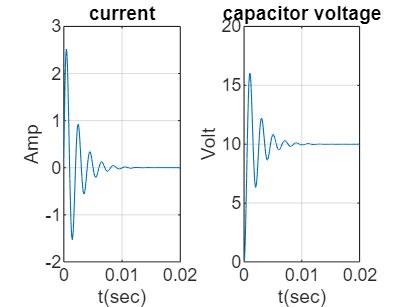


close all; clearvars;
global R C L V
R=1;
C=100e-6;
L=1e-3;
V=10;

x0 = [0; 0];
tspan = [0 0.02];
[t, x] = ode45(@myRCL, tspan, x0);

% we can extract the system variables and save them in a file 'dataRCL'
iL = x(:,1);
vC = x(:,2);
save dataRCL t iL vC
vL = V - R*iL - vC;

% Plot the results
subplot(1,2,1), plot(t, iL), title('current');
xlabel('t(sec)'), ylabel('Amp'), grid;
subplot(1,2,2), plot(t, vC), title('capacitor voltage');
xlabel('t(sec)'), ylabel('Volt'), grid;

Use another subplot option: 

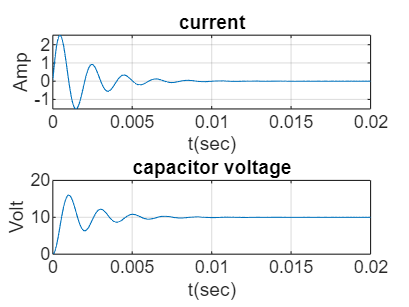

subplot(2,1,1), plot(t, iL), title('current');
xlabel('t(sec)'), ylabel('Amp'), grid;
subplot(2,1,2), plot(t, vC), title('capacitor voltage');
xlabel('t(sec)'), ylabel('Volt'), grid;

Other options to save data in file:

save dataRCL.txt t iL vC -ascii


See also xlswrite for saving to MS Excel!